close all
clear
clc

定义仿真时间范围和时域采样点数

T = 2;
N = 2000;

生成采样时刻和矩形脉冲的时域波形

t = linspace(-T/2,T/2-T/N,N)';
f = (t>-1/2&t<1/2);

定义待计算的频谱范围和频域采样点数

OMG = 16*pi;
K = 1000;

生成待计算频点，初始化频谱变量

omg = linspace(-OMG/2,OMG/2-OMG/K,K)';
F = zeros(size(omg));

遍历所有频点计算频谱，每个频点用信号波形矢量和复指数波形矢量的内积计算

for k = 1:K
    F(k) = T/N*exp(-1j*omg(k)*t).'*f;
end

初始化合成信号变量

fs = zeros(size(t));

与正变换类似，遍历采样时刻计算合成时域信号波形，每个时刻用频谱加权复指数函数值得到

for n = 1:N
    fs(n) = OMG/2/pi/K*exp(1j*omg*t(n)).'*F;
end

绘图：左子图是时域波形，包括直接定义的信号和合成的信号

figure;
subplot(1,2,1), hold on, box on;
plot(t,f,'k-');
plot(t,real(fs),'k-.');
set(gca,'YLim',[-.5 1.5],'FontSize',16);
xlabel('t');
ylabel('f(t)');
legend('f(t)','f_s(t)');

右子图是频谱

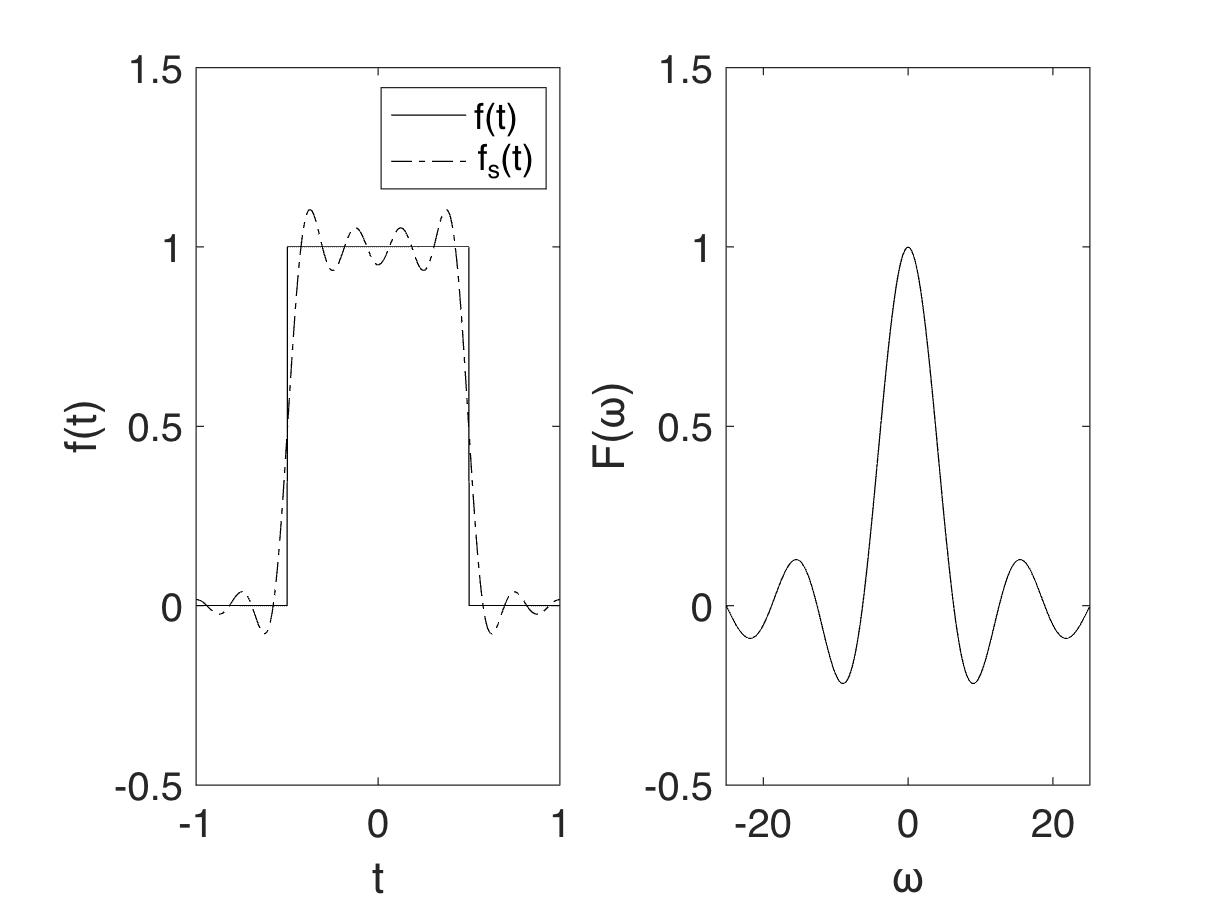

subplot(1,2,2), hold on, box on;
plot(omg,real(F),'k-');
set(gca,'XLim',[-8*pi,8*pi],'YLim',[-0.5 1.5],'FontSize',16);
xlabel('\omega');
ylabel('F(\omega)');